for IMG_IDX = 1:7
% HYPERPARAMETERS
% IMG_IDX = 7;
TARGET_BRIGHTNESS = 30;
JND_FACTOR = 3;

% Reference images
ref_imgs = ["beach.jpg"; "galaxy.jpeg"; "orig.jpg"; "peacock.jpeg"; "tiger.jpg"; "toronto.jpg"; "xmas.jpg"];

% Load the image
img = imread(ref_imgs(IMG_IDX));

% Reduce the brightness
orig_brightness = compute_brightness(img);
reduction = TARGET_BRIGHTNESS/orig_brightness;
img = reduce_brightness(img, reduction,'multiply');
orig_brightness = compute_brightness(img);

% Resize image 
% img = imresize(img, [360 480]); 

% Display the image
imshow(img);

% Display the average pixel intensity
disp(['Original intensity: ' num2str(compute_brightness(img))]);

Original intensity: 41.2324


Original intensity: 32.007


Original intensity: 31.0982


Original intensity: 32.6245


Original intensity: 32.2041


Original intensity: 31.3989


Original intensity: 32.9517


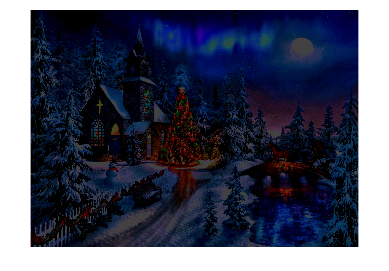

img_YCbCr = rgb2ycbcr(img);
Y = img_YCbCr(:,:,1);
enhanced = img_YCbCr;
enhanced(:,:,1) = imadjust(Y);
enhanced = ycbcr2rgb(enhanced); % convert back to RGB

% Compute the average pixel intensity
enhanced_brightness = compute_brightness(enhanced);
factor = orig_brightness / enhanced_brightness;
while factor < 1
    enhanced = reduce_brightness(enhanced, factor,'multiply');
    enhanced_brightness = compute_brightness(enhanced);
    factor = round(orig_brightness / enhanced_brightness, 2);
end    

imshow(enhanced);

disp(['Enhanced intensity: ' num2str(compute_brightness(enhanced))]);

Enhanced intensity: 41.2811


Enhanced intensity: 31.9833


Enhanced intensity: 31.087


Enhanced intensity: 32.7292


Enhanced intensity: 32.3251


Enhanced intensity: 31.4669


Enhanced intensity: 32.9289


% type = 'Yang'; % idk what this parameter is lol
% 
% % Convert RGB to YCbCr
% img_YCbCr = rgb2ycbcr(img);
% Y = img_YCbCr(:,:,1);
% 
% % Compute the JND thresolds at a pixel level
% jnd_Y = JND_pixel(Y, type);
% 
% % Visualize the JND thresholds
% imagesc(jnd_Y)
% colorbar
% 
% % Compute the mean JND threshold
% jnd_Y = JND_FACTOR.*jnd_Y;
% jnd_mean = mean2(jnd_Y)
% jnd_mod = jnd_Y - jnd_mean;
% 
% % Update image based on the JND thresholds from the Y channel to generate a new image
% new_img = img_YCbCr;
% new_img(:,:,1) = uint8(double(Y) + round(jnd_mod));
% new_img = ycbcr2rgb(new_img); % convert back to RGB
% new_img(new_img < 0) = 0;
% new_img(new_img > 255) = 255;

% % Display the new image
% imshow(new_img)
% 
% % Compute the average pixel intensity
% new_brightness = compute_brightness(new_img);
% intensity_dif = new_brightness - orig_brightness;
% 
% % Adjustment (if needed)
% while intensity_dif > 0
%     new_img = reduce_brightness(new_img, intensity_dif,'subtract');
%     new_brightness = compute_brightness(new_img);
%     intensity_dif = ceil(new_brightness - orig_brightness);
% end
% 
% % Display the average pixel intensity
% disp(['JND intensity: ' num2str(new_brightness)]);

% Save the images to an output directory
imwrite(img, ['output/input_image_' num2str(orig_brightness) '.jpg'], 'jpg');
% imwrite(new_img, ['output/output_image_jnd_' num2str(new_brightness) '.jpg'], 'jpg');
imwrite(enhanced, ['output/output_image_enhanced_' num2str(enhanced_brightness) '.jpg'], 'jpg');
end